# Target Tracking in Highway Scenario through MHE algorithm

clear 
close all
clc

startup

## Load the Data & processing

addpath("../simulation/SimulationData")
load("cameraData.mat"); % camera data 
load("radarData.mat"); %  radar data
load("GT.mat"); % ground truth

## Estimation Algorithm parameters

% building the vector with measured data

% position data taken from camera
ymeas = radar_data.Detections.Measurement;
ymeas = ymeas.Data(:,:,:);
ymeas = squeeze(ymeas); % remove dimensions of 1
xy_pos = ymeas(1:2,:);

% speed data taken from the radar sensor measurements better, camera
% contains sparse speed sensor data
ymeas_radar = radar_data.Detections.Measurement;
ymeas_radar = ymeas_radar.Data(:,:,:);
ymeas_radar = squeeze(ymeas_radar);
speed = sqrt(ymeas_radar(4,:).^2 + ymeas_radar(5,:).^2);

% building the measurement vector
ymeas = [xy_pos;speed];
N = length(speed); % number of samples

% filter parameter
nz = 5; % number of states
ny = 3; % number of measured output
nu = 2; % number of inputs
Ts = 0.1; % sensors sampling time
Msec            =   1; % Seconds of Moving Horizon Estimator window
M               =   round(Msec/Ts); % number of steps in the window
MHE_interval = 1; % number of steps at which we want the optimization algorithm to be solved

%% Initialize optimization variables
x0 = [ymeas(1,1);ymeas(2,1);ymeas(3,1);0;0;        % initial state
      0.01*ones(2*M+2,1)];    % disturbances/input noise
z_est = zeros(nz,N);

%% Solution -  BFGS
% Initialize solver options
myoptions               =   myoptimset;
myoptions.Hessmethod  	=	'BFGS';
myoptions.gradmethod  	=	'CD';
myoptions.graddx        =	2^-17;
myoptions.tolgrad    	=	1e-8;
myoptions.ls_beta       =	0.2;
myoptions.ls_c          =	.01;
myoptions.ls_nitermax   =	1e2;
myoptions.nitermax      =	1e3;
myoptions.xsequence     =	'on';
myoptions.outputfcn     =   @(x)target_cost(x,M,Ts,ymeas);

tic
% estimation along the whole simulated trajectory
for ind = M+1:MHE_interval:N
    % Run solver
    % ymeas_M = ymeas(:,ind-M:ind) % take M+1 elements out of measurement
    % vector
    [xstar,fxstar,niter,exitflag,xsequence] = myfminunc(@(x)target_cost(x,M,Ts,ymeas(:,ind-M:ind)),x0,myoptions);
    % simulation of the system with optimal solution
    z_minus_M_t = xstar(1:nz,1); % z(-M|t) of current iteration, aka estimated initial state of the system
    d_course = [xstar(6:6+M,1)';xstar(6+M+1:end,1)']; % course of disturbance
    
    %% Run simulation with FFD
    time_FFD    =   [0:0.01:M*Ts];
    Nblock      =   Ts/0.01;
    Nsim_FFD    =   length(time_FFD);
    
    z_sim      =   zeros(5,Nsim_FFD);
    z_sim(:,1) =   z_minus_M_t;

    % system simulation to compute stage costs at ith time instant
    for iind=2:Nsim_FFD
        d                  =   d_course(:,1+floor(time_FFD(iind)/Ts));
        zdot               =   CTCV_model(0,z_sim(:,iind-1),0,d,0);
        z_sim(:,iind)       =   z_sim(:,iind-1)+Ts/Nblock*zdot;
    end
    x0 = [z_sim(1,end); z_sim(2,end); z_sim(3,end);0;0;xstar(6:6+M,1);xstar(6+M+1:end,1)];
    z_est(:,ind-M) = [z_sim(1,end); z_sim(2,end); z_sim(3,end);z_sim(4,end);z_sim(5,end)];
end

Iteration       NormGrad          Cost      Rel. cost         Rel. x      Line-search
        0    5.96184e+08   5.77549e+03    1.00000e+00    1.00000e+00                0
        1    2.02547e+08   4.79714e+03    1.69397e-01    5.41964e-02                8
        2    3.13594e+07   4.67319e+03    2.58392e-02    3.84596e-02                8
        3    7.91273e+07   4.61264e+03    1.29556e-02    1.46811e-02                8
        4    1.06908e+07   4.57557e+03    8.03671e-03    8.58311e-03                9
        5    2.43623e+05   4.56512e+03    2.28392e-03    4.88130e-02                7
        6    3.99315e+05   4.45085e+03    2.50322e-02    7.59310e-01                4
        7    7.11342e+04   4.35651e+03    2.11946e-02    2.47960e-01                5
        8    3.43455e+04   4.21144e+03    3.33005e-02    1.69844e+00                3
        9    2.10542e+04   4.16730e+03    1.04813e-02    1.11511e-01                4
       10    7.63505e+03   4.06875e+03    2.36474e-02 

      189    8.59036e-07   9.49822e+00    2.80717e-13    1.76132e-14               13
Local minimum possible, relative step size smaller than tolerance
Iteration       NormGrad          Cost      Rel. cost         Rel. x      Line-search
        0    3.82605e+09   3.40492e+03    1.00000e+00    1.00000e+00                0
        1    7.40394e+07   7.41593e+01    9.78220e-01    1.98354e-05                8
        2    1.01045e+07   5.22344e+01    2.95646e-01    2.78586e-06                8
        3    1.83906e+06   3.21630e+01    3.84256e-01    1.08794e-06                8
        4    3.66230e+03   2.90092e+01    9.80566e-02    4.77830e-07                8
        5    1.47474e+03   2.90018e+01    2.57176e-04    1.93797e-08                8
        6    2.99220e+06   2.61071e+01    9.98085e-02    9.03661e-06                4
        7    2.38405e+02   2.21028e+01    1.53381e-01    2.11996e-05                8
        8    8.88521e+02   2.11809e+01    4.17070e-02    9.57764e-06      

      113    5.45573e-01   6.59262e-01    9.59903e-15    5.30979e-18               16
Local minimum possible, relative step size smaller than tolerance
Iteration       NormGrad          Cost      Rel. cost         Rel. x      Line-search
        0    3.96123e+06   4.37151e+01    1.00000e+00    1.00000e+00                0
        1    4.78159e+05   3.67652e+01    1.58980e-01    1.48183e-06                8
        2    4.48832e+05   3.58309e+01    2.54123e-02    5.45025e-07                8
        3    1.04628e+06   3.08754e+01    1.38304e-01    3.57257e-06                7
        4    2.53731e+04   2.97073e+01    3.78314e-02    1.83147e-06                8
        5    1.63129e+03   2.86610e+01    3.52225e-02    7.91340e-05                4
        6    6.60804e+02   2.82973e+01    1.26880e-02    3.85137e-06                5
        7    9.77524e+02   2.74339e+01    3.05128e-02    1.37139e-05                4
        8    3.21248e+02   2.61329e+01    4.74214e-02    2.34283e-05      

      186    5.05280e+08   4.50667e+03    0.00000e+00    1.79294e-18               22
Local minimum possible, relative step size smaller than tolerance
Iteration       NormGrad          Cost      Rel. cost         Rel. x      Line-search
        0    3.90547e+11   5.02761e+04    1.00000e+00    1.00000e+00                0
        1    7.95740e+08   2.30342e+04    5.41846e-01    3.05944e-04                8
        2    4.91810e+07   2.16422e+04    6.04331e-02    1.38239e-05                8
        3    2.12049e+08   2.12312e+04    1.89897e-02    8.84477e-05                6
        4    1.20364e+07   2.08937e+04    1.58942e-02    1.68376e-05                8
        5    3.15167e+06   2.08720e+04    1.04028e-03    1.94830e-06                8
        6    6.86566e+06   1.92196e+04    7.91699e-02    6.29015e-04                4
        7    3.36984e+06   1.51980e+04    2.09246e-01    1.58632e-03                4
        8    1.59161e+06   1.13705e+04    2.51841e-01    9.58721e-04      

      224    7.74445e+01   4.36353e+03    9.87301e-08    1.56251e-04                2
      225    1.01087e-03   4.36353e+03    2.17188e-08    1.66087e-04                7
      226    9.11270e-04   4.36353e+03    1.07157e-07    1.15987e-04                0
      227    7.16870e-03   4.36353e+03    1.56931e-07    1.24785e-04                0
      228    2.38781e-04   4.36353e+03    1.19546e-07    1.74583e-04                1
      229    9.31505e-03   4.36353e+03    2.49891e-08    5.57056e-05                0


      230    1.67976e+00   4.36353e+03    3.15170e-08    8.84189e-05                2
      231    2.81205e-04   4.36353e+03    5.33894e-09    1.07406e-04                5
      232    1.20240e-01   4.36353e+03    3.79227e-08    2.18376e-05                0
      233    2.02927e-04   4.36353e+03    4.93371e-08    8.91265e-05                3
      234    2.52419e-04   4.36353e+03    4.92949e-09    2.84182e-05                0
      235    2.45886e-04   4.36353e+03    1.34184e-08    1.13206e-04                0
      236    6.07158e-04   4.36353e+03    7.92708e-09    5.47388e-05                0
      237    1.92665e-04   4.36353e+03    2.97940e-09    1.75937e-05                1
      238    3.41786e-04   4.36353e+03    1.23608e-08    2.08644e-05                0
      239    2.31913e-04   4.36353e+03    1.69528e-08    4.27812e-05                0
      240    5.04625e-04   4.36353e+03    1.36037e-08    2.36939e-05                0
      241    9.96053e-05   4.36353e+03    3.68865e-10 

      133    4.16854e+04   5.95585e+03    1.08759e-03    2.56563e-02                2
      134    5.77623e+00   5.95164e+03    7.07687e-04    4.50667e-02                5
      135    8.83335e+00   5.95086e+03    1.30243e-04    1.04877e-02                0
      136    6.88634e+00   5.94482e+03    1.01539e-03    1.11872e-02                0
      137    4.21655e+00   5.94371e+03    1.85804e-04    3.23716e-03                1
      138    1.67574e+00   5.94119e+03    4.24419e-04    4.88844e-03                0
      139    2.90512e+00   5.93989e+03    2.19007e-04    1.48529e-03                0
      140    1.37787e+00   5.93804e+03    3.11398e-04    3.04190e-03                0
      141    1.47996e+00   5.93709e+03    1.60175e-04    1.22894e-03                0
      142    2.02810e+00   5.93603e+03    1.78309e-04    3.79853e-03                0
      143    3.29573e+00   5.93447e+03    2.62253e-04    5.99701e-03                0
      144    2.99214e+00   5.93202e+03    4.13465e-04 

      265    8.53771e-01   5.83685e+03    8.84431e-13    8.08885e-07                6
Local minimum possible, relative cost decrease smaller than tolerance
Iteration       NormGrad          Cost      Rel. cost         Rel. x      Line-search
        0    2.64373e+10   8.72003e+04    1.00000e+00    1.00000e+00                0
        1    1.19441e+15   3.22789e+04    6.29831e-01    2.20784e-05                8
        2    1.60440e+09   3.01122e+04    6.71245e-02    1.22392e-05               15
        3    1.37943e+08   2.96655e+04    1.48316e-02    2.79418e-05                7
        4    1.99780e+07   2.95989e+04    2.24828e-03    1.66536e-06                8
        5    4.65793e+06   2.95607e+04    1.28857e-03    6.52400e-07                8
        6    1.21344e+07   2.92851e+04    9.32459e-03    8.22054e-06                6
        7    3.16915e+07   2.76659e+04    5.52897e-02    1.22394e-04                5
        8    2.00014e+09   2.71961e+04    1.69822e-02    1.33506e-05  

      181    9.72214e-05   1.10251e+03    4.95396e-11    8.96970e-05                0
      182    1.40632e-06   1.10251e+03    7.42438e-15    2.44447e-11               12
Local minimum possible, relative cost decrease smaller than tolerance
Iteration       NormGrad          Cost      Rel. cost         Rel. x      Line-search
        0    2.87875e+12   1.03497e+05    1.00000e+00    1.00000e+00                0
        1    2.51472e+10   7.42815e+04    2.82284e-01    1.04828e-04                9
        2    7.40632e+09   2.84133e+04    6.17492e-01    4.92013e-05                8
        3    2.06856e+08   1.50528e+04    4.70219e-01    3.02781e-05                8
        4    1.28192e+08   1.42736e+04    5.17682e-02    2.26007e-05                7
        5    1.57679e+10   1.39023e+04    2.60121e-02    4.47559e-06                8
        6    6.78316e+06   1.36293e+04    1.96325e-02    3.74841e-06               11
        7    2.41395e+06   1.23227e+04    9.58660e-02    7.39298e-05  

      129    4.53009e+01   1.59524e+00    2.19437e-01    1.15021e-02                0
      130    4.74770e-01   1.48684e+00    6.79472e-02    6.41202e-03                3
      131    1.58062e-01   1.37885e+00    7.26314e-02    3.25464e-04                0
      132    1.53534e-01   1.27921e+00    7.22663e-02    1.69510e-04                0
      133    7.61591e-02   1.19784e+00    6.36082e-02    3.41253e-03                0


      134    1.22608e+01   1.11866e+00    6.60989e-02    2.20802e-03                0
      135    1.66621e-01   9.46022e-01    1.54329e-01    9.15924e-03                2
      136    8.63578e-02   8.61386e-01    8.94643e-02    1.55834e-03                0
      137    9.80471e-02   7.85060e-01    8.86085e-02    3.53312e-03                0
      138    4.47027e-01   6.87660e-01    1.24067e-01    3.93675e-03                0
      139    5.82946e-02   6.23541e-01    9.32423e-02    5.53770e-03                1
      140    9.49036e-02   5.67595e-01    8.97227e-02    4.50855e-03                0


      141    5.51386e-01   5.06287e-01    1.08013e-01    8.46278e-03                0
      142    3.77013e-02   5.05443e-01    1.66762e-03    4.78687e-04                3
      143    5.48510e-02   4.77914e-01    5.44660e-02    4.07918e-04                0
      144    1.69776e-02   4.47506e-01    6.36251e-02    1.44927e-03                0
      145    1.64947e-01   4.32661e-01    3.31735e-02    7.34852e-04                0
      146    8.85357e-02   4.09912e-01    5.25806e-02    1.82235e-03                1
      147    1.40098e-01   3.78863e-01    7.57435e-02    5.78949e-03                0
      148    1.70550e-02   3.74693e-01    1.10083e-02    3.85265e-03                0
      149    4.82828e-02   3.58933e-01    4.20606e-02    6.14973e-04                0
      150    3.42954e-02   3.18654e-01    1.12217e-01    7.63970e-04                0
      151    5.62735e-03   2.90054e-01    8.97530e-02    1.28932e-03                0


      152    1.17943e+00   2.82239e-01    2.69433e-02    4.09711e-04                0
      153    1.06551e-02   2.77757e-01    1.58805e-02    2.66421e-03                2
      154    2.53736e-02   2.69061e-01    3.13092e-02    1.78952e-05                0
      155    5.64980e-03   2.64683e-01    1.62696e-02    2.62176e-04                1
      156    4.36300e-03   2.60830e-01    1.45586e-02    1.62566e-04                0
      157    1.25066e-02   2.56955e-01    1.48545e-02    2.93723e-04                0


      158    5.57453e-01   2.44651e-01    4.78859e-02    1.32759e-03                0
      159    3.97809e-02   2.25121e-01    7.98261e-02    9.47525e-03                1
      160    2.42770e-02   2.03311e-01    9.68830e-02    1.99432e-03                0
      161    2.24237e-01   1.87418e-01    7.81691e-02    1.42928e-04                0
      162    1.41373e-02   1.79231e-01    4.36852e-02    1.86709e-03                1
      163    1.77260e-02   1.70243e-01    5.01456e-02    1.59809e-04                0
      164    5.42021e-03   1.70162e-01    4.74657e-04    4.84957e-05                2
      165    1.26034e-03   1.66952e-01    1.88643e-02    3.12941e-05                0
      166    8.30859e-04   1.66064e-01    5.32333e-03    4.96970e-05                0
      167    1.28149e-03   1.65366e-01    4.20069e-03    5.86936e-05                0
      168    3.32417e-04   1.64722e-01    3.89369e-03    1.55792e-04                0
      169    2.28927e-03   1.64446e-01    1.67381e-03 

      174    1.53967e+00   1.60246e-01    4.72080e-04    1.22258e-04                3
      175    5.27186e-03   1.60233e-01    7.94483e-05    5.44715e-05                5
      176    5.07818e-03   1.56288e-01    2.46212e-02    1.32304e-04                0
      177    9.13002e-04   1.53568e-01    1.74027e-02    2.51423e-05                0
      178    3.19676e-03   1.52843e-01    4.72656e-03    1.07653e-04                0
      179    5.97978e-03   1.50088e-01    1.80253e-02    4.68918e-04                0
      180    7.50024e-03   1.43459e-01    4.41640e-02    1.10350e-03                0


      181    2.75485e-01   1.31930e-01    8.03635e-02    1.77690e-03                0
      182    1.03352e-01   9.39365e-02    2.87983e-01    8.27120e-03                1
      183    3.39303e-02   8.14126e-02    1.33323e-01    3.83285e-03                1
      184    4.77535e-03   7.64592e-02    6.08433e-02    1.90005e-03                0


      185    2.74767e-01   7.15819e-02    6.37901e-02    7.03738e-04                0
      186    1.37336e-02   6.05086e-02    1.54694e-01    7.39542e-03                1
      187    2.93543e-02   5.20817e-02    1.39268e-01    1.23890e-03                0
      188    2.53547e-02   4.30049e-02    1.74281e-01    4.54819e-03                0
      189    3.03172e-02   3.64450e-02    1.52537e-01    2.82998e-03                0
      190    2.20776e-02   3.64450e-02    2.99046e-09    1.28434e-10               11
      191    2.64846e-03   3.58078e-02    1.74844e-02    6.27645e-04                1
      192    2.83404e-03   3.46925e-02    3.11458e-02    2.52194e-04                0
      193    9.65471e-04   3.30548e-02    4.72063e-02    4.11111e-04                0
      194    2.78134e-02   3.19341e-02    3.39047e-02    3.01419e-04                0
      195    1.41041e-03   2.77510e-02    1.30991e-01    1.80872e-03                1
      196    2.43216e-03   2.58334e-02    6.91024e-02 

      197    5.97124e-01   2.20781e-02    1.45363e-01    1.33345e-03                0
      198    4.68215e-03   1.27610e-02    4.22009e-01    5.84121e-03                2


      199    3.73056e-01   8.18091e-03    3.58911e-01    1.50058e-03                0
      200    3.76632e-03   4.70278e-03    4.25151e-01    4.81208e-03                2
      201    7.61434e-04   4.19456e-03    1.08070e-01    2.13022e-03                0


      202    1.26080e-03   3.52105e-03    1.60567e-01    8.69739e-04                0


      203    8.41354e-03   2.48658e-03    2.93795e-01    1.68096e-03                0
      204    4.96317e-03   1.91060e-03    2.31635e-01    2.49953e-03                1
      205    7.18447e-04   1.86782e-03    2.23930e-02    4.14495e-04                1
      206    6.12511e-04   1.51093e-03    1.91070e-01    1.84872e-04                0
      207    2.70815e-03   1.14317e-03    2.43402e-01    6.10878e-05                0
      208    3.22252e-04   9.37248e-04    1.80131e-01    9.47793e-05                1
      209    1.58719e-04   7.10631e-04    2.41789e-01    1.13637e-05                0
      210    2.35956e-05   6.33409e-04    1.08667e-01    3.18995e-05                0
      211    2.21986e-05   6.17905e-04    2.44772e-02    2.25852e-05                0
      212    2.56481e-04   5.98947e-04    3.06819e-02    3.08322e-05                0
      213    1.25348e-05   5.72920e-04    4.34549e-02    8.38187e-05                1
      214    1.82975e-05   5.61318e-04    2.02493e-02 

      216    1.74126e-03   5.27254e-04    3.02425e-02    4.78299e-05                0
      217    3.00448e-05   5.00798e-04    5.01766e-02    1.68564e-04                2
      218    2.19180e-05   4.88830e-04    2.38974e-02    4.11495e-05                0
      219    1.35444e-04   4.70358e-04    3.77890e-02    1.59742e-05                0
      220    7.58483e-05   4.52370e-04    3.82436e-02    4.88447e-05                1
      221    3.60630e-05   4.34050e-04    4.04975e-02    1.86455e-04                0
      222    3.22200e-05   4.16494e-04    4.04453e-02    4.72422e-05                0
      223    1.12038e-04   3.91803e-04    5.92838e-02    3.99403e-05                0
      224    2.62616e-05   3.41686e-04    1.27915e-01    2.51522e-04                0
      225    3.27951e-05   3.28942e-04    3.72969e-02    2.84433e-05                0
      226    4.62526e-05   3.02123e-04    8.15297e-02    8.09028e-05                0


      227    2.01400e-03   2.61376e-04    1.34870e-01    2.07859e-04                0


      228    7.36056e-04   2.38263e-04    8.84266e-02    1.88357e-04                2
      229    4.90066e-05   1.98658e-04    1.66225e-01    3.40356e-04                1
      230    1.27401e-03   1.59074e-04    1.99258e-01    6.30740e-06                0
      231    2.89793e-05   1.30705e-04    1.78333e-01    3.14172e-05                2
      232    3.13592e-06   1.18568e-04    9.28626e-02    4.05195e-05                0
      233    1.65164e-05   1.15657e-04    2.45476e-02    1.53281e-05                0
      234    3.05533e-05   1.00466e-04    1.31351e-01    8.81105e-05                0
      235    5.68841e-06   7.69143e-05    2.34422e-01    2.29124e-04                0
      236    1.42671e-05   6.89754e-05    1.03217e-01    6.68204e-05                0
      237    4.62013e-06   6.54872e-05    5.05719e-02    3.63715e-05                0
      238    9.11381e-06   6.22325e-05    4.96997e-02    5.06224e-06                0
      239    9.87601e-06   6.00101e-05    3.57121e-02 

      240    2.52963e-04   5.77229e-05    3.81125e-02    7.07593e-05                0


      241    5.95060e-03   5.77187e-05    7.38287e-05    1.97167e-06                4


      242    2.08521e+04   5.77187e-05    0.00000e+00    3.20197e-24               25
Local minimum possible, relative step size smaller than tolerance
Iteration       NormGrad          Cost      Rel. cost         Rel. x      Line-search
        0    6.77828e+13   1.05099e+06    1.00000e+00    1.00000e+00                0
        1    4.22570e+10   9.49272e+04    9.09679e-01    1.09467e-04                9
        2    1.49111e+10   9.06306e+04    4.52614e-02    1.36690e-05                8
        3    2.11319e+11   7.30149e+04    1.94369e-01    9.44096e-06                8
        4    3.16371e+08   5.76291e+04    2.10721e-01    5.48919e-06               10
        5    3.47797e+07   5.70474e+04    1.00938e-02    1.19635e-06                8
        6    1.01483e+07   5.52616e+04    3.13033e-02    1.00355e-05                6
        7    1.25589e+07   5.51556e+04    1.91790e-03    1.13237e-06                7
        8    2.40310e+07   4.37911e+04    2.06045e-01    2.14096e-04      

      128    7.48159e+04   7.97538e+03    1.62775e-03    5.48498e-02                3
      129    1.07070e+02   7.96929e+03    7.63482e-04    3.88775e-02                5
      130    2.03560e+01   7.92050e+03    6.12156e-03    5.28519e-03                0
      131    1.79566e+01   7.90491e+03    1.96904e-03    6.16479e-03                0
      132    5.49563e+00   7.89419e+03    1.35636e-03    2.84707e-03                0
      133    1.17533e+01   7.88958e+03    5.83037e-04    8.63664e-04                0
      134    2.07273e+00   7.88255e+03    8.91915e-04    4.48931e-03                0
      135    4.58795e+00   7.88088e+03    2.11663e-04    4.79770e-03                0
      136    1.82471e+01   7.87694e+03    4.99579e-04    1.66944e-02                0
      137    2.01528e+01   7.87365e+03    4.17711e-04    1.71534e-02                1
      138    5.96405e+00   7.87074e+03    3.69500e-04    2.04970e-02                1
      139    5.47342e+00   7.86689e+03    4.88938e-04 

      113    3.22032e+05   8.33399e+03    1.94338e-03    1.08588e-02                4
      114    5.84051e+01   8.33080e+03    3.82253e-04    2.23007e-03                7
      115    2.87028e+01   8.30994e+03    2.50450e-03    5.46462e-03                0
      116    1.73378e+01   8.30229e+03    9.20814e-04    2.52241e-03                0
      117    4.25402e+00   8.29371e+03    1.03317e-03    3.08296e-03                0
      118    5.11924e+00   8.29055e+03    3.81449e-04    7.00523e-04                0
      119    4.14306e+00   8.28707e+03    4.19147e-04    1.65758e-03                0
      120    5.12664e+00   8.28422e+03    3.44123e-04    4.17864e-04                0
      121    2.95587e+00   8.28094e+03    3.95240e-04    1.66485e-03                0
      122    3.48505e+00   8.27873e+03    2.67140e-04    8.97734e-04                0
      123    5.52051e-01   8.27686e+03    2.25789e-04    6.66831e-04                0
      124    1.18514e+00   8.27640e+03    5.57793e-05 

      144    2.58948e-02   1.12449e+02    1.35420e-07    2.90790e-05                2
      145    8.11582e-06   1.12449e+02    2.44699e-09    4.50900e-06                5
      146    2.33929e-05   1.12449e+02    4.87934e-08    1.23638e-06                0
      147    3.33249e-06   1.12449e+02    2.25618e-08    5.19909e-07                1
      148    8.67270e-07   1.12449e+02    1.51454e-08    2.30301e-07                0
      149    7.54568e-07   1.12449e+02    4.34339e-09    2.20067e-07                0
      150    9.32208e-07   1.12449e+02    1.80963e-09    3.68599e-07                0
      151    1.72116e-06   1.12449e+02    6.69931e-11    1.30954e-09                4
      152    3.38511e-07   1.12449e+02    1.50515e-09    4.05846e-07                1
      153    4.06407e-05   1.12449e+02    1.58376e-09    4.43233e-07                0
      154    3.82976e-07   1.12449e+02    5.24937e-09    2.42184e-06                2
      155    1.69927e-06   1.12449e+02    2.65586e-09 

      158    3.93043e-03   1.12449e+02    8.11149e-09    5.25152e-06                0
      159    2.82963e-07   1.12449e+02    4.06177e-09    5.72311e-06                4
      160    3.21030e-06   1.12449e+02    1.41966e-09    1.99422e-07                0
      161    4.84609e-07   1.12449e+02    8.15602e-10    1.21805e-06                1
      162    1.42082e-07   1.12449e+02    1.15600e-09    2.03971e-07                0
      163    1.36532e-06   1.12449e+02    9.63224e-10    2.54526e-07                0
      164    2.38056e-07   1.12449e+02    3.63661e-10    4.38069e-07                1
      165    2.30617e-07   1.12449e+02    7.34417e-10    2.56710e-08                0
      166    9.45310e-08   1.12449e+02    5.59795e-12    5.25951e-11                6
      167    1.33235e-07   1.12449e+02    3.05693e-10    4.63045e-07                0
      168    8.44749e-08   1.12449e+02    1.67367e-11    2.96846e-09                3
      169    5.12286e-06   1.12449e+02    1.11187e-10 

      171    3.34070e-05   1.12449e+02    3.01462e-11    7.97897e-08                1
      172    2.09659e-08   1.12449e+02    9.29822e-11    2.52783e-07                4
      173    5.45205e-08   1.12449e+02    6.44518e-15    5.21248e-15               10
Local minimum possible, relative step size smaller than tolerance
Iteration       NormGrad          Cost      Rel. cost         Rel. x      Line-search
        0    2.47731e+12   3.70196e+05    1.00000e+00    1.00000e+00                0
        1    1.64373e+15   2.39545e+05    3.52926e-01    1.82932e-04                8
        2    2.42380e+10   4.76775e+04    8.00966e-01    1.85345e-05               13
        3    2.47274e+08   2.28949e+04    5.19797e-01    1.64024e-05                8
        4    3.33196e+07   2.24483e+04    1.95052e-02    1.68786e-06                8
        5    1.32259e+07   2.22731e+04    7.80634e-03    2.60533e-06                7
        6    4.01336e+07   2.21603e+04    5.06140e-03    2.51286e-06      

      148    1.28392e+06   3.81084e+03    9.74712e-04    7.29399e-03                3
      149    1.13135e+00   3.80922e+03    4.25862e-04    7.02558e-03                8
      150    2.85324e+00   3.80828e+03    2.45666e-04    6.31950e-04                0
      151    1.36843e+00   3.80646e+03    4.77781e-04    2.44378e-03                0
      152    1.53238e+00   3.80545e+03    2.64973e-04    7.99474e-04                0
      153    6.23967e-01   3.80448e+03    2.56722e-04    9.92705e-04                0
      154    6.06436e-01   3.80404e+03    1.15616e-04    5.38657e-04                0
      155    2.02191e+00   3.80354e+03    1.30227e-04    2.05049e-03                0
      156    9.37051e-01   3.80240e+03    3.01396e-04    9.38312e-03                0
      157    2.27510e+00   3.80165e+03    1.96950e-04    5.61700e-04                0
      158    1.64139e+00   3.80093e+03    1.89919e-04    5.04679e-03                0
      159    7.18443e-01   3.80076e+03    4.36740e-05 

      119    9.12283e-02   5.92248e-01    2.96817e-09    1.25428e-07                2
      120    7.65133e-07   5.92248e-01    3.59433e-10    2.80304e-08               10
      121    1.92777e-07   5.92247e-01    1.08710e-06    9.99630e-07                0
      122    7.06684e-07   5.92247e-01    1.85486e-07    2.62909e-07                0
      123    1.15077e-07   5.92247e-01    1.23172e-07    3.15761e-07                1
      124    1.98934e-07   5.92247e-01    1.19003e-07    5.25619e-07                0
      125    9.02565e-07   5.92247e-01    1.66518e-07    1.09766e-06                0
      126    1.24098e-07   5.92247e-01    1.46847e-08    2.17542e-07                2
      127    4.37361e-07   5.92247e-01    1.07754e-07    3.11905e-07                0
      128    5.04241e-07   5.92247e-01    5.84594e-07    1.27656e-06                0
      129    1.15586e-05   5.92246e-01    9.03646e-07    1.23358e-06                0
      130    1.04079e-06   5.92245e-01    2.12814e-06 

      323    2.03376e+02   4.58376e+03    1.98417e-16    1.56791e-15               19
Local minimum possible, relative step size smaller than tolerance
Iteration       NormGrad          Cost      Rel. cost         Rel. x      Line-search
        0    2.45541e+09   1.50969e+04    1.00000e+00    1.00000e+00                0
        1    5.45116e+08   1.43959e+04    4.64364e-02    9.43288e-07                9
        2    7.24162e+08   1.39997e+04    2.75175e-02    2.45659e-06                8
        3    3.23925e+06   1.37978e+04    1.44230e-02    8.29717e-07                9
        4    2.56539e+06   1.37884e+04    6.82259e-04    8.61469e-07                7
        5    2.11791e+07   1.37038e+04    6.13662e-03    5.11410e-06                6
        6    6.99748e+06   1.28289e+04    6.38406e-02    2.18081e-04                5
        7    2.76705e+06   1.26045e+04    1.74932e-02    1.57149e-05                6
        8    1.46558e+06   1.19411e+04    5.26308e-02    3.67792e-05      

       59    3.71891e+07   5.53458e+01    1.97303e-02    4.62363e-04                7
       60    9.96919e-01   5.47195e+01    1.13157e-02    3.37617e-04               11
       61    5.32023e-01   5.42819e+01    7.99830e-03    5.22602e-04                0
       62    4.47160e-01   5.39192e+01    6.68013e-03    1.07494e-04                0
       63    4.38927e-01   5.35985e+01    5.94846e-03    1.98646e-05                0
       64    9.86718e-01   5.32447e+01    6.60010e-03    9.35247e-05                0
       65    1.40037e+00   5.24971e+01    1.40425e-02    2.96591e-04                0
       66    2.45150e+00   5.14044e+01    2.08129e-02    6.13538e-04                0
       67    2.72902e+00   4.96512e+01    3.41062e-02    1.05444e-03                0
       68    3.29663e+01   4.71965e+01    4.94390e-02    1.30021e-03                0
       69    6.65273e+00   4.34991e+01    7.83410e-02    3.63954e-03                1
       70    2.17083e+00   3.95924e+01    8.98100e-02 

      143    6.22905e+06   3.33336e+03    9.75791e-02    6.80521e-02                4
      144    1.62807e+03   3.32885e+03    1.35384e-03    9.81948e-03                7
      145    2.84468e+03   3.09125e+03    7.13767e-02    5.84769e-04                1
      146    8.45372e+02   2.86063e+03    7.46044e-02    3.02723e-02                1
      147    5.78681e+02   2.75075e+03    3.84108e-02    6.78040e-03                1
      148    5.95648e+02   2.68935e+03    2.23212e-02    4.40896e-03                0
      149    3.03858e+02   2.59749e+03    3.41572e-02    6.85525e-05                1
      150    5.40969e+01   2.48897e+03    4.17757e-02    6.29508e-03                0
      151    2.23250e+01   2.45655e+03    1.30281e-02    7.27449e-03                0
      152    3.79386e+01   2.43932e+03    7.01455e-03    3.86556e-03                0
      153    1.38505e+01   2.41510e+03    9.92847e-03    1.54595e-02                0
      154    1.27431e+01   2.40730e+03    3.22906e-03 

toc

Elapsed time is 867.657594 seconds.


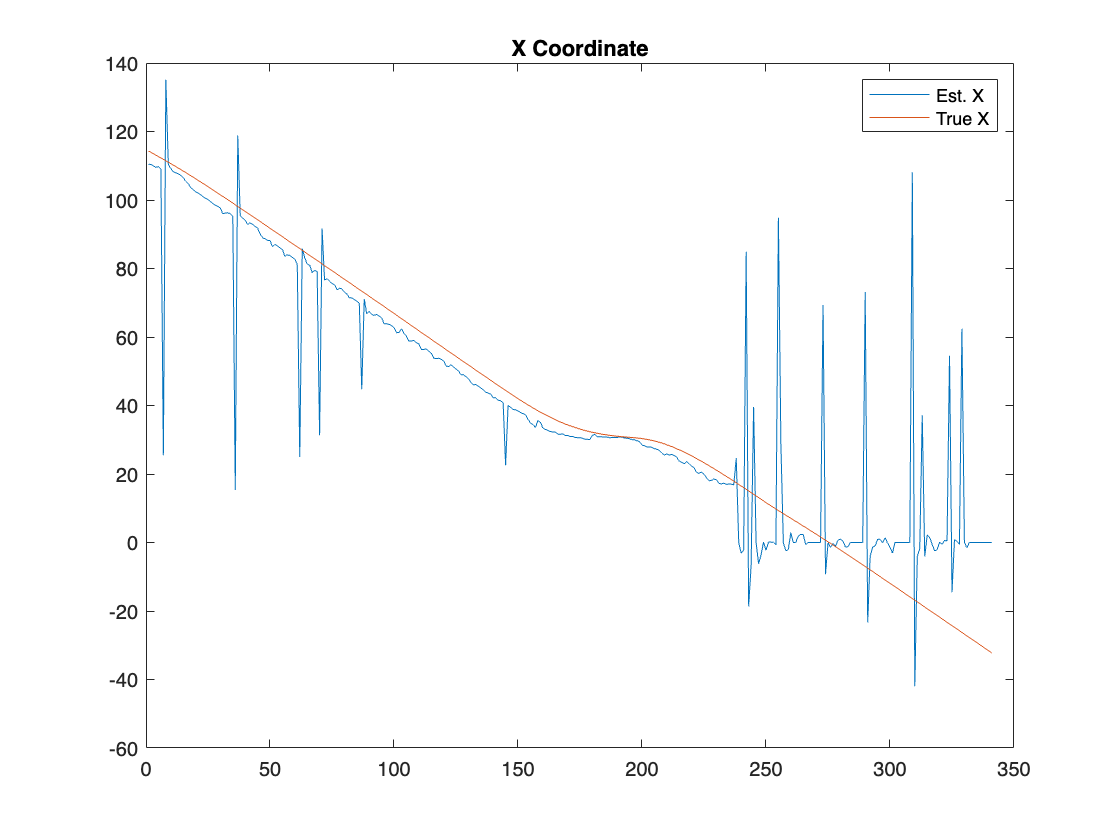

% check results against ground truth
gt_pos = ground_truth.Actors.Position.Data;
gt_pos = squeeze(gt_pos);

figure(1)
plot(z_est(1,:)), hold on
plot(gt_pos(1,:))
title('X Coordinate')
legend('Est. X','True X')
hold off

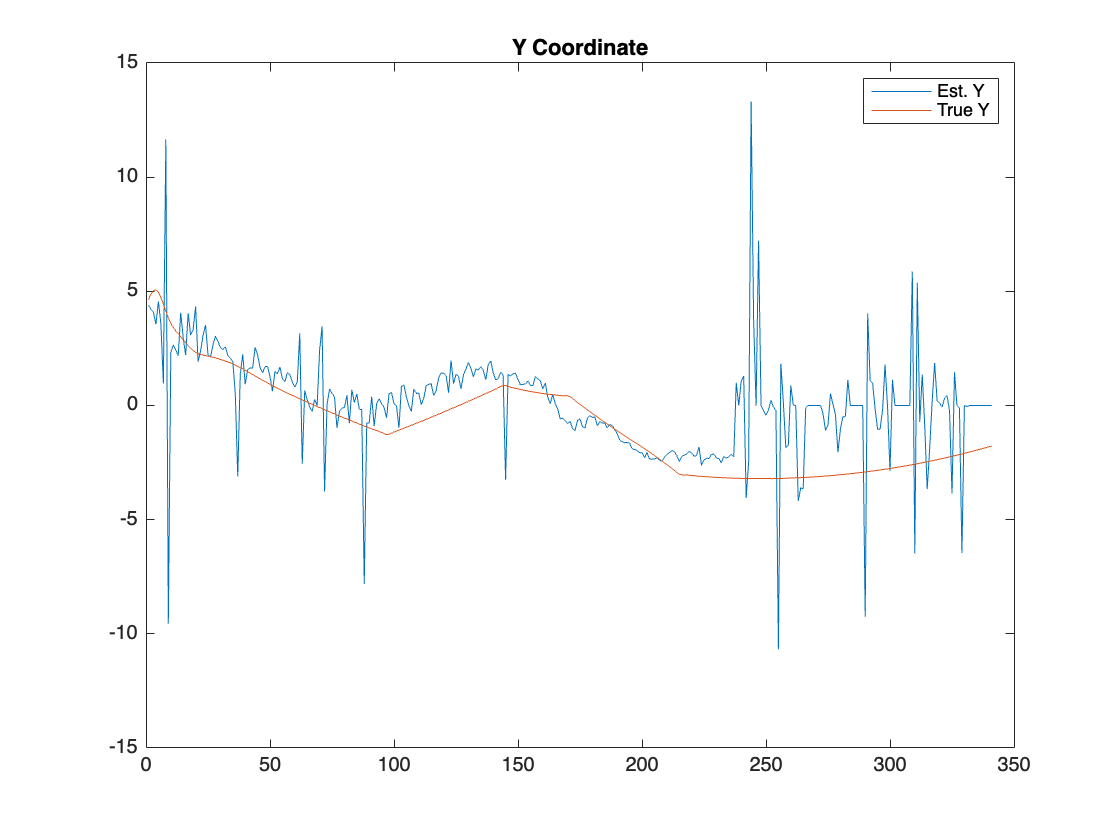


figure(2)
plot(z_est(2,:)), hold on
plot(gt_pos(2,:))
title('Y Coordinate')
legend('Est. Y','True Y')
hold off